# Inpainting Workflow

## Add File Paths

addpath 'Inpainting'
addpath 'Models'
addpath 'Common Functions'

## Load Files

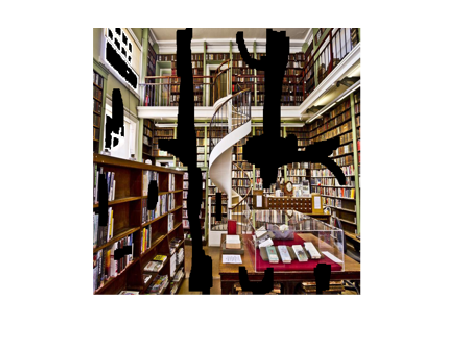

Image_name = 'library.png';
mask_name = 'library_mask.png';
% Load image
image = im2double(imread(Image_name));
mask  = imread(mask_name);

mask = im2double(mask);
mask = mask > 0.5;
mask = repmat(mask, [1 1 3]);

img = image .* mask;
img = imresize(img, [256, 256]);
mask = imresize(mask, [256, 256]);
inpainted_image = img;
imshow(inpainted_image);

## Define CNN and Noise Tensor

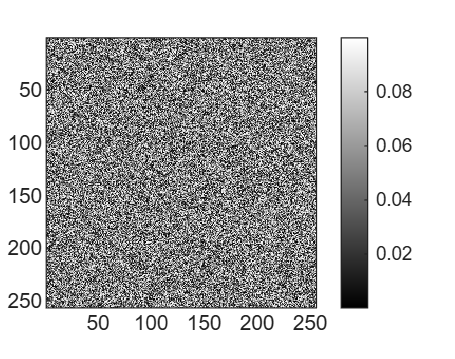

% --- Create Noise Tensor ---
input_depth = 32;
%method = 'meshgrid';
method = 'noise';
spatial_size = size(inpainted_image, 1);
net_input = get_noise(input_depth, method, spatial_size);

% Visualize Noise
imagesc(net_input(:,:,2))
axis image
colormap gray
colorbar


% --- Create CNN ---
num_classes = 3; % Number of color channels
[a, b, ~] = size(inpainted_image);
imgSize = [a, b, input_depth]; % Set the image size for the CNN
%net = InpaintUnet(imgSize, num_classes);
%net = DipUnet3(imgSize, num_classes);
%net = InpaintUnet2(imgSize, num_classes);
net = InpaintUnet3(imgSize, num_classes);
% Compute number of parameters
totalParams = 0;
lrnables = net.Learnables;
for i = 1:height(lrnables)
    param = lrnables.Value{i};
    totalParams = totalParams + numel(extractdata(param));
end
fprintf('Number of params: %d\n', totalParams);

Number of params: 1027379



%--- Define Loss Function ---
%loss = mean((out - inpainted_image).^2,'all');
function loss = computeLoss(out, img_noisy, lambda_tv) 
 
mse_loss = mean((out - img_noisy).^2, 'all'); 
%Total Variation: penalise spatial gradients in output 
dx = out(:, 2:end, :, :) - out(:,1:end-1, :, :); 
dy = out(2:end, :, :, :) - out(1:end-1, :, :, :); 
tv_loss = mean(abs(dx),'all') + mean(abs(dy), 'all'); 
loss = mse_loss + lambda_tv * tv_loss; 
end

## Optimization Step 1

function [loss, gradients, out, out_avg] = modelGradients(net, net_input_saved, img_inpaint, mask, out_avg, exp_weight, reg_noise_std)

    %img_inpaint = dlarray(img_inpaint,'SSCB');
    img_inpaint  = dlarray(single(img_inpaint),  'SSCB');
    mask         = dlarray(single(mask),         'SSCB');
    %mask = dlarray(mask, 'SSCB');

    if reg_noise_std > 0
        noise = randn(size(extractdata(net_input_saved)), 'single');
        noise = dlarray(noise, 'SSCB');
        net_input = net_input_saved + noise*reg_noise_std;
    else
        net_input = net_input_saved;
    end

    % Forward pass
    out = forward(net, net_input);

    % Loss (MSE)
    %loss = mean((out.*mask - img_inpaint.*mask).^2,'all');
    loss = computeLoss(out.*mask, img_inpaint.*mask, 1e-32);

    % Output smoothing (detach)
    out_detached = dlarray(extractdata(out),'SSCB');

    if isempty(out_avg)
        out_avg = out_detached;
    else
        out_avg = out_avg*exp_weight + out_detached*(1-exp_weight);
    end

    % Gradients
    gradients = dlgradient(loss, net.Learnables);

end



## Optimization step 2

Iteration 00001 Loss 0.112415 PSNR: 7.3803
Iteration 00002 Loss 0.095372 PSNR: 8.1275
Iteration 00003 Loss 0.087408 PSNR: 8.3241
Iteration 00004 Loss 0.084408 PSNR: 8.5536
Iteration 00005 Loss 0.070146 PSNR: 8.9329
Iteration 00006 Loss 0.064478 PSNR: 9.4108
Iteration 00007 Loss 0.059368 PSNR: 9.6966
Iteration 00008 Loss 0.056778 PSNR: 9.8023
Iteration 00009 Loss 0.055000 PSNR: 9.8778
Iteration 00010 Loss 0.053119 PSNR: 9.9672
Iteration 00011 Loss 0.051663 PSNR: 10.0942
Iteration 00012 Loss 0.050767 PSNR: 10.2195
Iteration 00013 Loss 0.049825 PSNR: 10.3312
Iteration 00014 Loss 0.048970 PSNR: 10.4229
Iteration 00015 Loss 0.048052 PSNR: 10.4932
Iteration 00016 Loss 0.047327 PSNR: 10.5381
Iteration 00017 Loss 0.046660 PSNR: 10.5766
Iteration 00018 Loss 0.045977 PSNR: 10.6120
Iteration 00019 Loss 0.045417 PSNR: 10.6411
Iteration 00020 Loss 0.044972 PSNR: 10.6806
Iteration 00021 Loss 0.044292 PSNR: 10.7215
Iteration 00022 Loss 0.043676 PSNR: 10.7658
Iteration 00023 Loss 0.043378 PSNR: 10.811

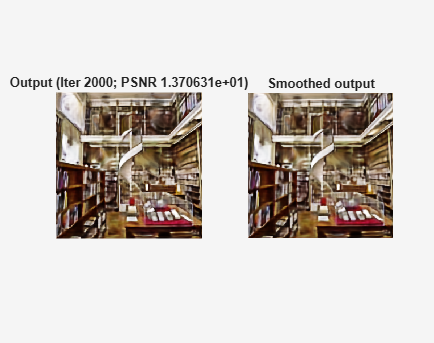

trailingAvg   = [];
trailingAvgSq = [];
reg_noise_std = 0.00;

PLOT = 1; % 1 for plotting and 0 otherwise
LR = 0.01;
show_every = 10;
exp_weight = 0.99;
num_iter = 2000;
%
out_avg = [];
last_net = [];
last_learnables = [];
psrn_inpaint_last = 0;
psnr_inpaint_last = -inf;

% Convert net_input to dlarray format
net_input_saved = dlarray(single(net_input), 'SSCB');


% --- Training Loop ---
for iter = 1:num_iter
    % Call function for forward pass
    [loss, gradients, out, out_avg] = dlfeval(@modelGradients, net, net_input_saved, inpainted_image, mask,  out_avg, exp_weight, reg_noise_std);
    
    
    [net, trailingAvg, trailingAvgSq] = adamupdate(net, gradients,trailingAvg, trailingAvgSq, iter, LR);
    

    % --- Convert dlarray to numeric ---
    out_num = double(gather(extractdata(out)));
    out_num = out_num(:,:,:,1);
    out_avg_num = double(gather(extractdata(out_avg)));
    out_avg_num = out_avg_num(:,:,:,1);


    %--- Compute PSNR ---
    psnr_inpaint = psnr(out_num, inpainted_image);
    
    % --- Print Loss and PSNR ---
    fprintf('Iteration %05d Loss %.6f PSNR: %.4f\r', iter,gather(extractdata(loss)),...
        psnr_inpaint);
    
    
    % --- Start Plotting ---
    if PLOT && mod(iter, show_every) == 0
        % Clip to [0, 1]
        out_plt = min(max(out_num, 0), 1);
        out_avg_plt = min(max(out_avg_num, 0), 1);
        % Plot side by side
        fig = figure(1); clf
        set(fig, 'Visible', 'on');
        subplot(1,2,1);
        imagesc(out_plt); colormap gray; axis image off;
        
        title(sprintf('Output (Iter %d; PSNR %d)', iter,psnr_inpaint));
        

        subplot(1,2,2);
        imagesc(out_avg_plt); colormap gray; axis image off;
        title('Smoothed output')
        drawnow 
    end

    % --- Back Tracking Logic ---
    if  mod(iter, show_every) ~= 0
        if psnr_inpaint - psnr_inpaint_last < -5
            fprintf('\n Falling back to previous checkpoint.\n');
            % Restore weights
            net.Learnables.Value = last_learnables;
            break; % stop training
        else
            % Save current weights
            last_learnables = net.Learnables.Value;
            psnr_inpaint_last = psnr_inpaint;
        end
    end

end